## Load and Explore Image Data

%digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
 %   'nndatasets','DigitDataset');

imds = imageDatastore('C:\Users\ferch\Desktop\gnu\Prueba', ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

Mostrar imagenes

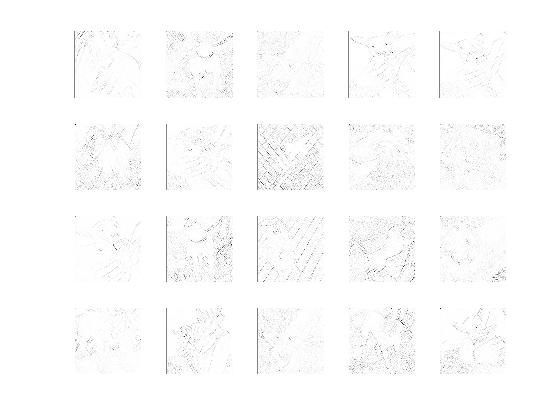

figure;
perm = randperm(150,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

labelCount = countEachLabel(imds)

labelCount = 4×2 table
       Label       Count
    ___________    _____

    agresividad     150 
    ansiedad        150 
    miedo           150 
    nada            150 


Dimensiones

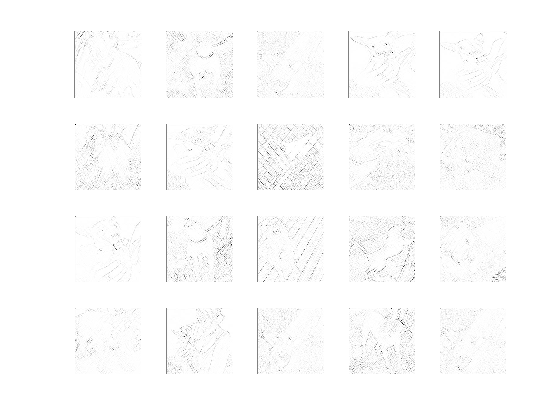

img = readimage(imds,1);
imshow(preview(imds));

size(img)

ans =    224   224


## Seleccionar valores de entrenamiento y validación

numTrainFiles = 115;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## Definir arquitectura de la red neuronal

layers = [
    imageInputLayer([224 224 1],"Name","imageinput")
    convolution2dLayer([11 11],96,"Name","conv1","Padding","same","Stride",[4 4])
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([3 3],"Name","maxpool","Padding","same","Stride",[2 2])
    convolution2dLayer([5 5],256,"Name","conv2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([3 3],"Name","maxpool2_1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","conv3","Padding","same")
    convolution2dLayer([3 3],384,"Name","conv4","Padding","same")
    convolution2dLayer([3 3],256,"Name","conv5","Padding","same")
    maxPooling2dLayer([3 3],"Name","maxpool2_2","Padding","same","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc1_1")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    fullyConnectedLayer(4096,"Name","fc1_2")
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_4")
    fullyConnectedLayer(4,"Name","fc1_3")
    batchNormalizationLayer("Name","batchnorm_5")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Especificar parametros de entrenamiento

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.005, ...
    'MaxEpochs',10, ...
    'MiniBatchSize',32, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

## Entrenado la red neuronal con los datos de entrenamiento

Loss es la entropia cruzada y accuracy es el porcentaje de imagenes que clasifica correctamente.

net = trainNetwork(imdsTrain,layers,options);

## Validación de imagenes clasificadas y exactitud

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

*Copyright 2012 The MathWorks, Inc.*